%CHANGES FOR 3D<->2D:::
%SETUP:             'CPz = CP(:,3)'
%CP FUNCTION:       'hold' needs 'targets' third position (z)
%DCP FUNCTION:      'P1' and 'P2' needs 'CP' third position (z)
%MAGMAT FUNCTION:   'Z' component in BOTH pos AND abs
%PLOTTING:          All XY plots --> XYZ plots
%NB:                MAG PLOTS DO NOT NEED THIRD AXIS
%Working with supposedly infinite control points
order = 7;
%Position
%Control Points
%idk what these are [0,0,10; 0,30,0; 20,100,10; 50,60,0; 80,100,10; 110,70,0; 50,40,20; 140,5,0; 170,5,0; 170,5,20; 200,30,20; 140,60,20; 50,40,0; 0,30,20];
%drone racetrack [0,0,5; 0,10,2; 0,30,0; 0,30,0; 10,100,2; 20,100,5; 20,100,5; 40,70,2; 50,60,0; 50,60,0; 70,90,2; 80,100,5; 80,100,5; 100,80,2; 110,70,0; 110,70,0; 60,50,5; 50,40,10; 50,40,10; 130,15,5; 140,5,0; 140,5,0;  170,5,0; 170,5,0; 180,5,2; 180,15,5; 160,15,7; 165,5,10 ;170,5,10; 170,5,10; 190,20,5; 200,30,10; 200,30,10; 150,50,10; 140,60,10; 140,60,10; 80,50,5; 50,40,0; 50,40,0; 30,35,5; 0,30,10;  0,30,10; 0,10,12; 0,0,5];
targets = [50,50,100; 50,40,95; 40,40,90; 40,60,85; 60,60,80; 60,30,75; 30,30,70; 30,70,65; 70,70,60; 70,20,55; 20,20,50; 20,80,45; 80,80,40; 80,10,35; 10,10,30; 10,90,25; 90,90,20; 90,0,15; 0,0,10; 0,100,5; 100,100,0]

targets =     50    50   100
    50    40    95
    40    40    90
    40    60    85
    60    60    80
    60    30    75
    30    30    70
    30    70    65
    70    70    60
    70    20    55


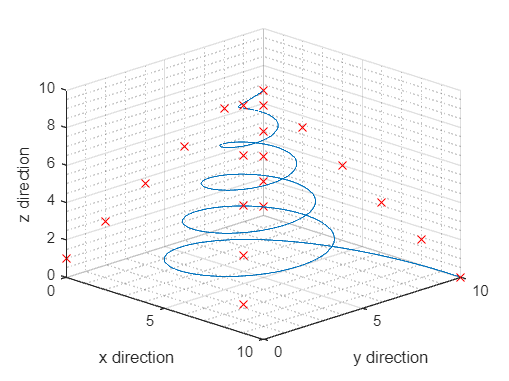

targets = 1/10 * targets;
CP = points(targets, order);
CPx = CP(:,1);
CPy = CP(:,2);
CPz = CP(:,3);
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 1/60;
%Knot Vector
sz = size(CP);
knot = knotvect(sz(1,1), order, pmin, pmax, pstep);
ksz = size(knot);
validpmin = knot(1, order);
validpmax = knot(1, (ksz(1,2)-order+1));
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
%Calulates B-spline for current conditions
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
%Lowers the order for derivative spline and calculates derivative points
order = 6;
CP = DCP(CP, knot, order);
%Derivative knots also
knot = Dkn(knot);
%Derivative spline can then be calculated using our evaluate function
VelMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
VMagMAT = absBS(VelMAT);
%Second Derivative
order = 5;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
AccMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
AMagMAT = absBS(AccMAT);
%Third Derivative
order = 4;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
JerkMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
JMagMAT = absBS(JerkMAT);
%Fourth Derivative
order = 3;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
SnapMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
SMagMAT = absBS(SnapMAT);
%plot Position and CP
plot3(PosMAT(:,1),PosMAT(:,2),PosMAT(:,3))
grid on
grid minor
hold on
view([45, 25]);
scatter3(CPx, CPy, CPz, 60, 'red', 'X')
xlabel('x direction')
ylabel('y direction')
zlabel('z direction')
%MGPC = [0,0,5; 0,30,0; 20,100,5; 50,60,0; 80,100,5; 110,70,0; 50,40,10; 140,5,0; 170,5,0; 170,5,10; 200,30,10; 140,60,10; 50,40,0; 0,30,10;]
%scatter3(MGPC(:,1), MGPC(:,2), MGPC(:,3), 800, 'O', 'Color', '"#77AC30"')
%scatter3([0;200], [0;100], [0;50], 'white')



hold off

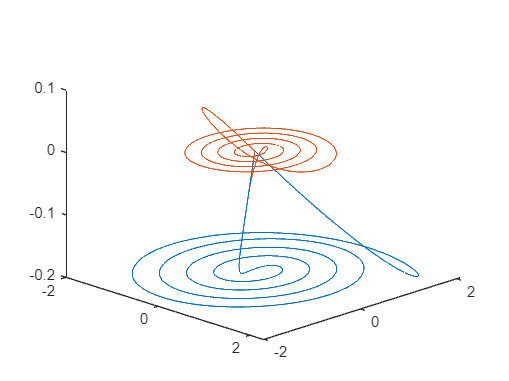

plot3(VelMAT(:,1),VelMAT(:,2), VelMAT(:,3))
hold on
view([45, 25]);
plot3(AccMAT(:,1),AccMAT(:,2), AccMAT(:,3))
hold off

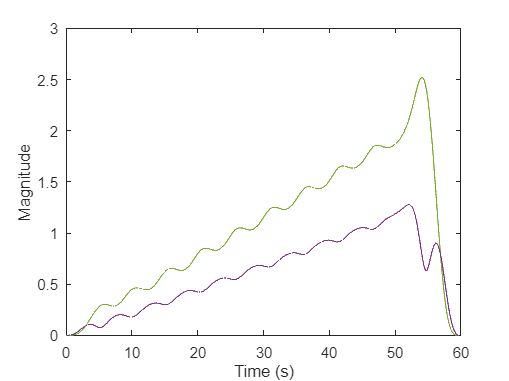

%NB MagMAT(1,n) holds the step (time), (2,n) holds magnitude
plot(VMagMAT(:,1)*pstep, VMagMAT(:,2), 'Color', "#77AC30")
hold on
plot(AMagMAT(:,1)*pstep, AMagMAT(:,2), 'Color', "#7E2F8E")
xlabel('Time (s)')
ylabel('Magnitude')
hold off

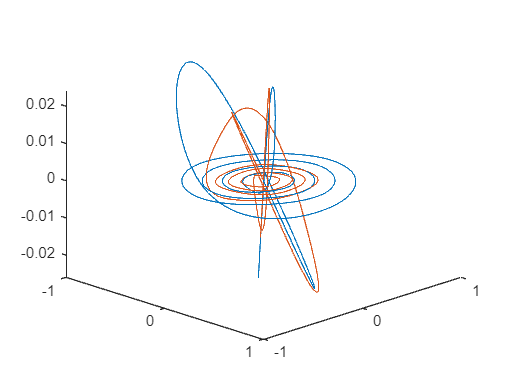

plot3(JerkMAT(:,1),JerkMAT(:,2), JerkMAT(:,3))
hold on
view([45, 25]);
plot3(SnapMAT(:,1),SnapMAT(:,2), SnapMAT(:,3))
hold off

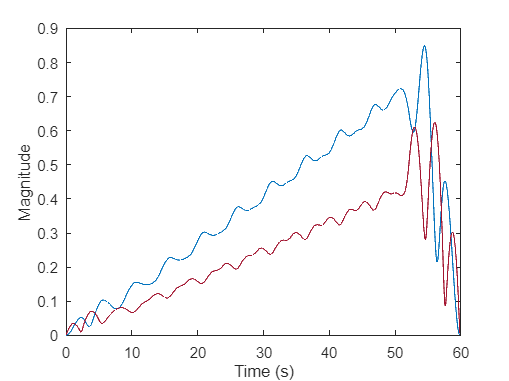

plot(JMagMAT(:,1)*pstep, JMagMAT(:,2), 'Color', 	"#0072BD")
hold on
plot(SMagMAT(:,1)*pstep, SMagMAT(:,2), 'Color', "#A2142F")
xlabel('Time (s)')
ylabel('Magnitude')
hold off

function CP = points(targets, order)
    %takes the hight of the targets matrix i.e. how many points
    P = height(targets);
    %initial and end points need to be repeated 'rep' times
    rep = order-2;
    CP = [];
    hold = [targets(1,1), targets(1,2), targets(1,3)];
    %Repeat initial
    for n = 1:1:rep
        CP = [CP; hold];
    end
    %Main Body
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2), targets(i,3)];
        CP = [CP; hold];
    end
    %Repeat end
    hold = [targets(P,1), targets(P,2), targets(P,3)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
    %Repeating CP ensures path passes through start and end
end
function Knot = knotvect(P, order, pmin, pmax, pstep)
    %K is the number of knots required
    K = P + order;
    Knot = pmin;
    %initial knots must be stacked
    %these are 1 time step away, as if equal would divide by zero later
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    %Main body of the vector
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    %final knots must also be stacked for open uniform
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    %This function calculates the NK constants
    %i.e. proportion of each bezier curve in the basis spline at step t
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
    %These constant are outputted as a matrix, with zeros in each column
    %to ensure only the correct bezier curve factors are included
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    %Initial NK Matrix is a simple 'on/off' for current steps knot (t)
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end
function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    %calculate the entire curve
    for p = pmin:pstep:pmax
        %only output within the valid region
        if p >= validpmin && p<=validpmax
            k = 2;
            %pMAT will change for each spline order
            NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
            %Product of each NK Matrix and its pMAT gives our spline
            k = 3;
            NK3MAT = NK2MAT*pMAT(p, knot, k);
            k = 4;
            %Nested if statements allows lower order spline outputs
            if order < k
                Pos = NK3MAT*CP;
                %Final step is to apply our NK product to the CPs
            else
                NK4MAT = NK3MAT*pMAT(p, knot, k);
                k = 5;
                if order < k
                    Pos = NK4MAT*CP;
                else
                    NK5MAT = NK4MAT*pMAT(p, knot, k);
                    k = 6;
                    if order < k
                        Pos = NK5MAT*CP;
                    else
                        NK6MAT = NK5MAT*pMAT(p, knot, k);
                        k = 7;
                        if order < k
                            Pos = NK6MAT*CP;
                        else
                            NK7MAT = NK6MAT*pMAT(p, knot, k);
                            Pos = NK7MAT*CP;
                        end
                    end
                end
            end
            %Output current coordinates to final spline
            BSplineMAT = [BSplineMAT; Pos];
            %Process repeats for each point along the curve
        end
    end
end
function DP = DCP(CP, knot, k)
    %Calulates derivative spline control points
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        %Takes current and next control point
        P1 = [CP(i,1),CP(i,2),CP(i,3)];
        P2 = [CP(i+1,1),CP(i+1,2),CP(i+1,3)];
        %Calculates derivative point-similar to Eulers method
        %--delta(x,y,z)*order/delta(knot)
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    %Derivatives knots are identicle to the original knots only dropping
    %first and last knots
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        Z = Pos(i,3);
        abs = sqrt(X^2+Y^2+Z^2);
        %MagMAT holds 'time' in x and 'abs' in y
        MagMAT = [MagMAT; i, abs];
    end
end